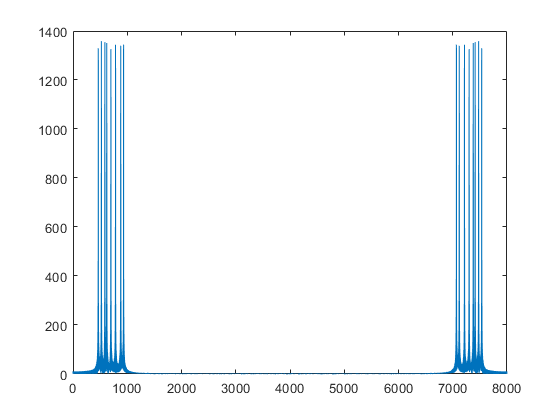

% -----------------------------------------------------------------------
% -------------- nahrávání (totální blbost) -----------------------------

% opravit na audiorecorder

% fs=11025; % vybereme vzorkovací frekvenci
% 
% disp('start');
% rec = wavrecord(3*fs,fs); % nahrávání (tři vteřiny)
% disp('stop');
% wavplay(rec,fs); % přehrání nahraného
% figure();
% plot(rec); % vykreslení grafu naší nahrávky
% wavplay(rec,fs/1.2); % přehrání nahraného pomaleji


% -----------------------------------------------------------------------
% ---------- vemem nahrávku a vyfiltrujeme ji část frekvencí ------------

rec=audioread('stupnice.wav'); % 'stupnice.wav' můžeme si zkusit filtrovat nějaký frekvence (8kHz)

fs=8000; % 'morse.wav' běží na 22050 fs, stupnice zas na 8000 fs

p = audioplayer(rec,fs); % můžeme přehrát
play(p);
input('Po skončení tónu stiskni ENTER');
rychla_furierova_transformace = abs(fft(rec)); %fast fourier transformation

pocet_vzorku=length(rec); % pocet vzorku

osa_frekvence = 0:fs/pocet_vzorku:(fs-(fs/pocet_vzorku)); % od nuly až do 22050(fs) s krokem vzorkovací frekvence lomeno pocet vzorků (to znamená normální trojčlenku)

plot(osa_frekvence,rychla_furierova_transformace);

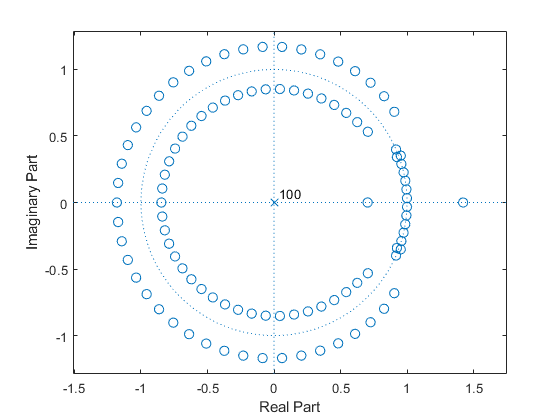



pocet_koeficientu=100; % počet koeficient; filtru (nevím co to znamená)

omega_zlomu=((((698.3333-622.3333)/2)+622.333)/(fs/2)); % vzorkovací frekvence děleno dvěma (fs/2) odpovídá omega normovaná rovno jedné  (omegaN = 1)... trojčlenkou můžeme dopočítat, kolik je omegaZlomu při nějaké vybrané fzlomu, nad kterou už chci signál vyfiltrovat
% 488.2559 a 2822.673 máme dvě špičky kde jednu z nich chci vyfiltrovat..
% takže zlomovou frekvenci zvolím přesně mezi nimi (průměr (x1+x2)/2)

vyfiltrovany_prubeh=fir1(pocet_koeficientu,omega_zlomu); %horni propust vytvořím, když přidám parametr ,'high'

figure();
zplane(vyfiltrovany_prubeh,1)

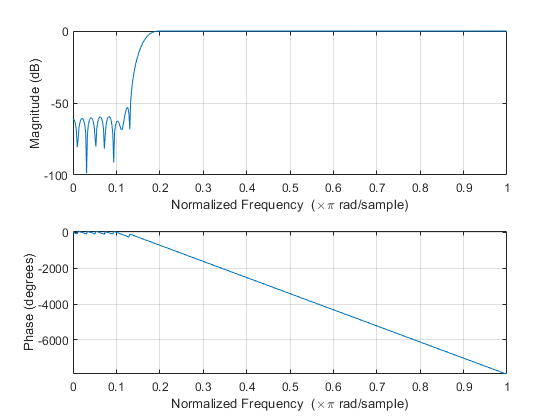

figure();
freqz(vyfiltrovany_prubeh,1)

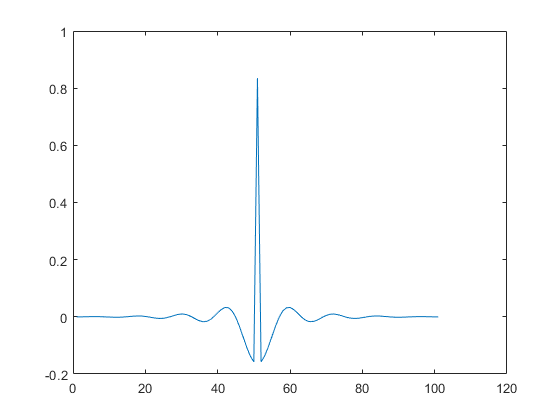

figure();
plot(vyfiltrovany_prubeh)

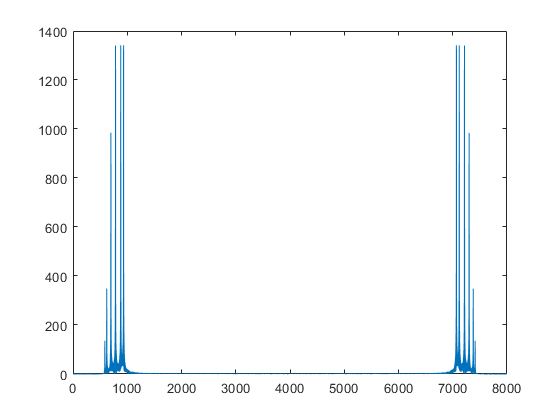


vysledek=conv(rec,vyfiltrovany_prubeh); % proženeme původní signál naším filtrem (dostanu ho vyfiltrovany)

rychla_furierova_transformace_vysledku = abs(fft(vysledek)); %fast fourier transformation

pocet_vzorku=length(vysledek); % pocet vzorku

osa_frekvence = 0:fs/pocet_vzorku:(fs-(fs/pocet_vzorku)); % od nuly až do 22050(fs) s krokem vzorkovací frekvence lomeno pocet vzorků (to znamená normální trojčlenku)

plot(osa_frekvence,rychla_furierova_transformace_vysledku);


p = audioplayer(vysledek,fs); % můžeme výsledek přehrát a zjistím že jsem odstranil jednu ze dvou složek morzeovky
play(p);
input('Po skončení tónu stiskni ENTER');